# Introduction to Unsupervised Learning

**Unsupervised learning** refers to a machine learning algorithm that infers information from a given dataset without any guidance. The algorithm relies on underlying similarities and patterns within the data to learn how the variables are related to one another. So in a way, we're "letting the data speak for itself."

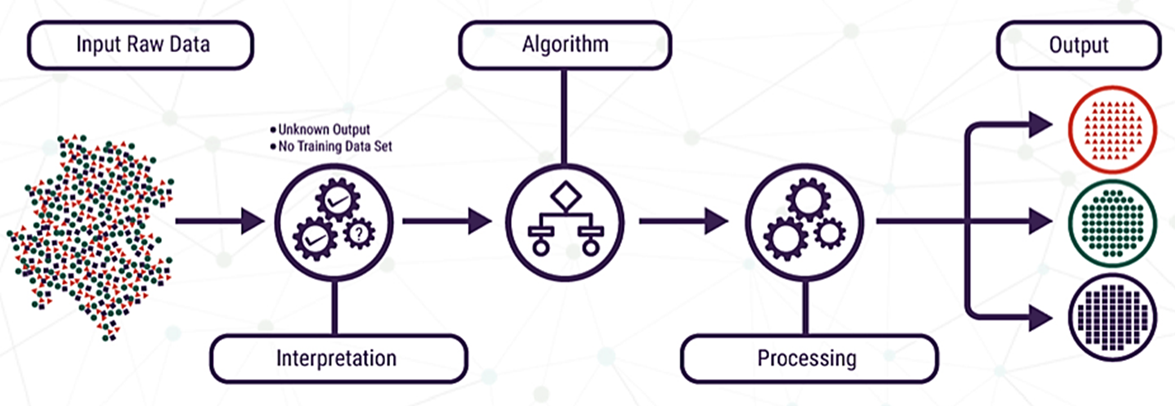

This is a great tool to use for initial exploration of a dataset without any defined hypothesis. Unsupervised learning is especially valuable in assessing a large dataset with multiple variables. For today's lecture, we'll be going over two broad applications of unsupervised learning: (1) **clustering** and (2) **dimensionality reduction**. 

# Clustering - Identifying distinct groups based on similarity

We'll be covering two types of clustering techniques: **hierarchical** and **k-means** clustering. To introduce these methods, we'll consider the following planetary data: 

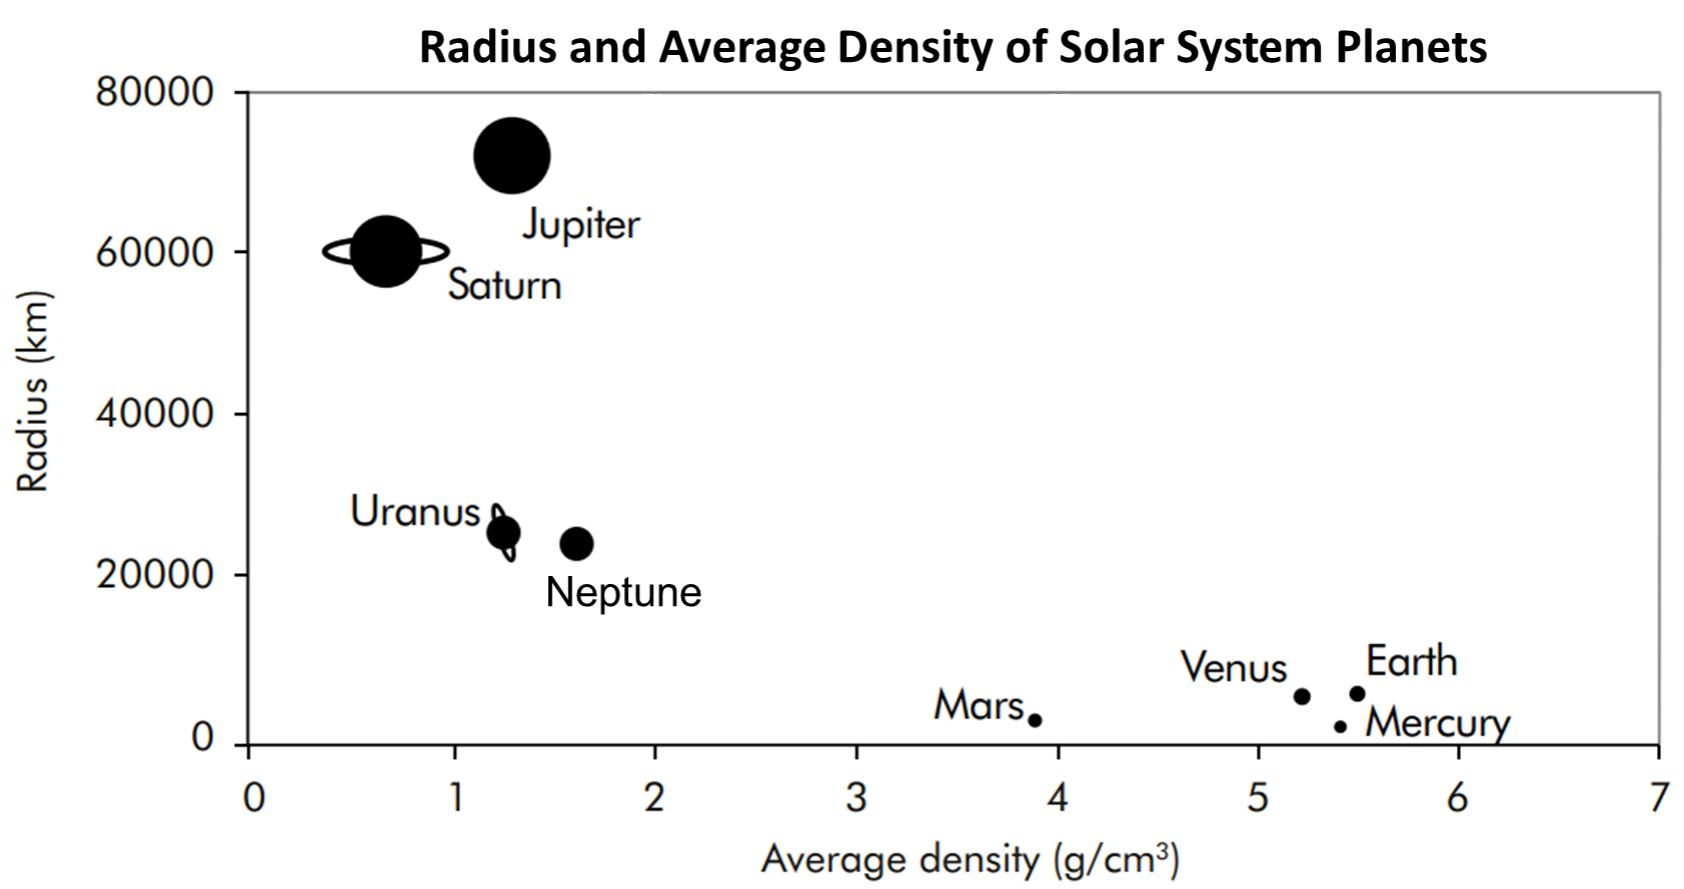

## Hierarchical Clustering

In **hierarchical clustering**, each observation starts in its own cluster at the base of the hierarchy. As we move up the hierarchy, observations that are most similar group together first until all observations are linked. This hierarchy of observations is often depicted as a **dendrogram**. In MATLAB, we can also plot a **clustergram** to visualize how similar the observations (e.g. planets) are based on different measurements (e.g. density, radius). The plot below shows an example of hierarchical clustering of planets in the solar system based on their average density and radius: 

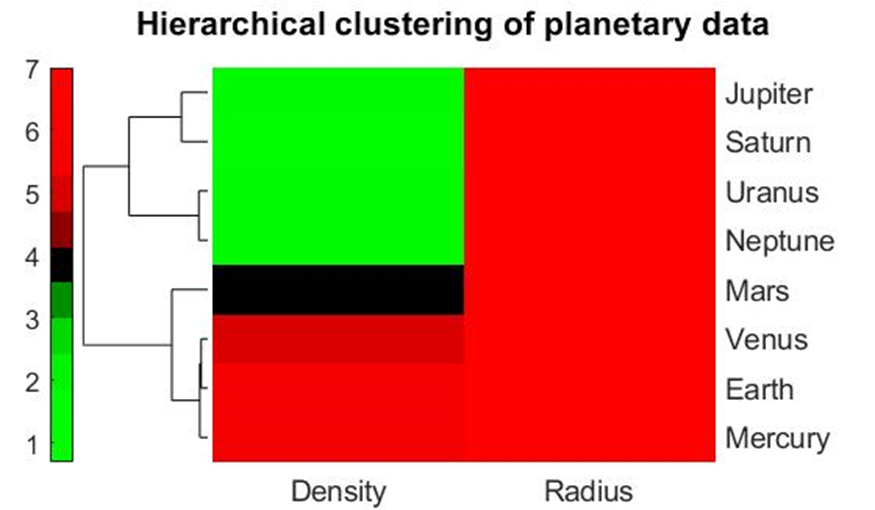

You may have noticed that the radius column doesn't show any differences between planets. This is because the range of values represented by the color gradient is limited to 1 through 7 (recall that planet radius was in the 10,000 range). To have a better visual sense in how a metric (e.g. radius) differs between observations (e.g. planets), we can **standardize** the values within a metric. Below is what the same clustergram of planetary data would look like with standardized density and radius: 

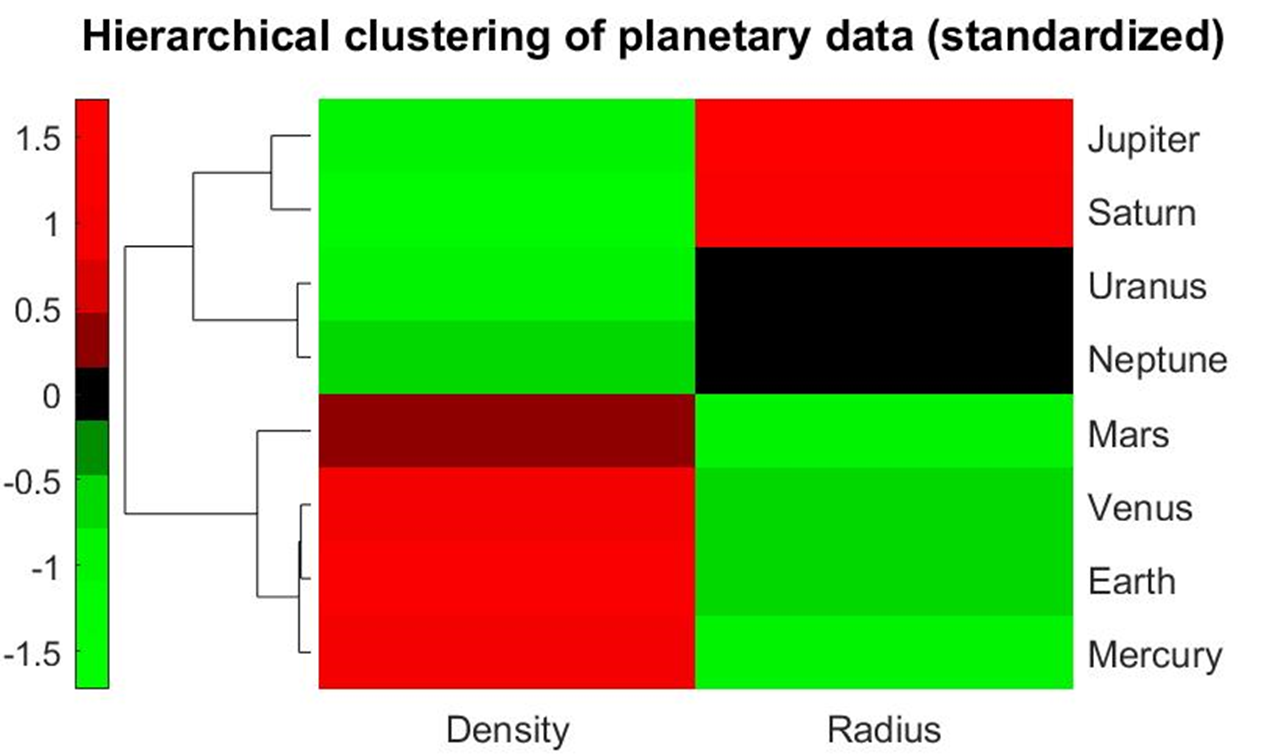

## Defining Similarity

One of the most common ways to apply unsupervised learning is to assess the similarity within a dataset. Similarity can be quantitatively described using a **distance metric** between two variables. There are various types of distance metrics that can be used, but we'll just go over two of the most common ones: **Euclidean **and **correlation** distance. The plot below shows how these distance metrics differ:

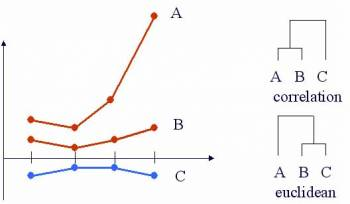

### Euclidean Distance

The **Euclidean distance** is broadly defined by the following formula: 


$$d\left(p,q\right)=\sqrt{\sum_{i=1}^n {\left(p_i -q_i \right)}^2 }$$


This is what the distance between p and q would look like when n = 2:

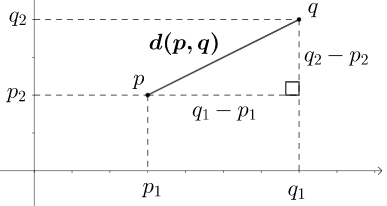

When analyzing biological data in MATLAB, we'll mostly be dealing with large vectors. In these cases, we let n be equal to the length of the vectors we're comparing (note: the vectors must have the same length). 

Let's try an example with two random vectors of length 4: 

% Define two random vectors with n = 4


We can calculate the Euclidean distance manually: 

% Calculate the Euclidean distance manually


Alternatively, we can use the built-in function `pdist` and set the distance type as `euclidean` :

% Calculate the Euclidean distance using pdist


Note that when using `pdist`, we combined vectors a and b into a matrix. This is because the `pdist` function is used to calculate the distance between all vectors in a matrix. If we had a matrix with three vectors, we would be calculating the distance for three pairwise combinations (C(3,2) = 3):

% Create a third vector of length 4


% Calculate the Euclidean distance between all 3 vectors


Note: Euclidean distance is the default metric for the `pdist` function.

### Correlation Distance

Another commonly used distance metric is **correlation**, and this is broadly defined as follows: 


$$d\left(p,q\right)=1-r$$


where r is the *correlation coefficient* between two vectors. 

Going back to our previously defined vectors, the correlation distance can be calculated manually:

% Manual calculation of correlation distance


Or using the `pdist` function and setting the distance type to `correlation`:

% Calculation of correlation distance using pdist


% Calculate the correlation distance between all 3 vectors


Note that the correlation distance can only range from 0 (similar) to 2 (dissimilar). 

Additional information: refer to the `pdist` documentation for all available distance metrics.

## K-means Clustering

For **k-means clustering**, we specify how many distinct groups we think that the data will cluster into. K-means clustering then allocates data points to a cluster by minimizing the in-cluster sum of squares (more on this later). The value for k is typically chosen based on *a priori* information we may have on the data. Referring back to our planetary data: 

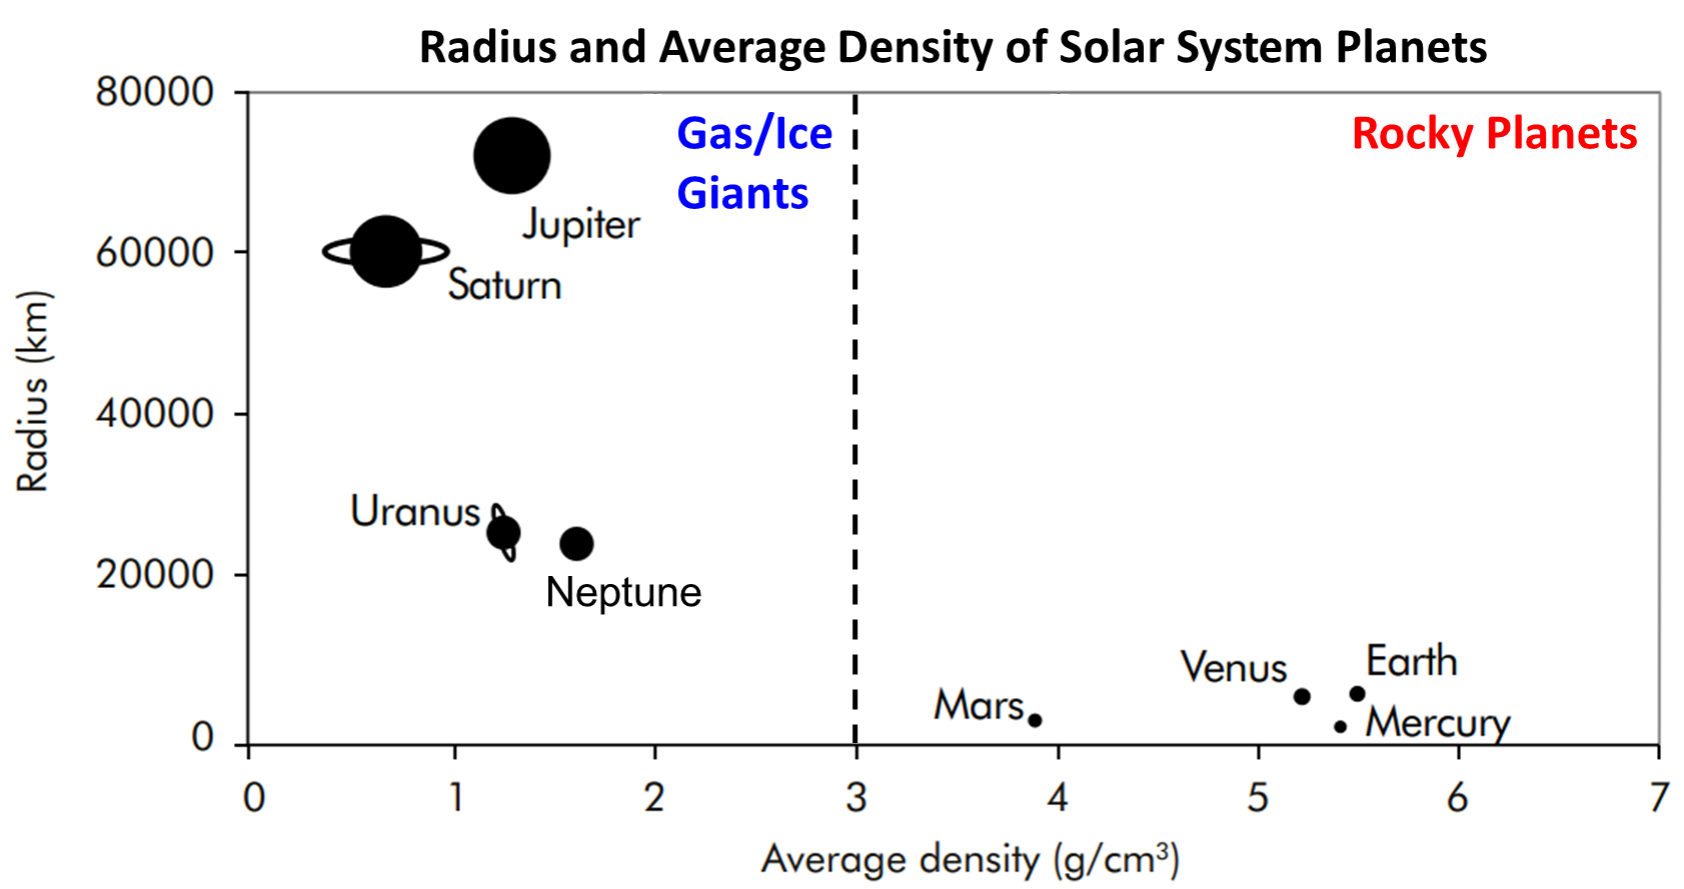

Based on this additional information, we could apply k-means clustering with k = 2 to group our planets: 

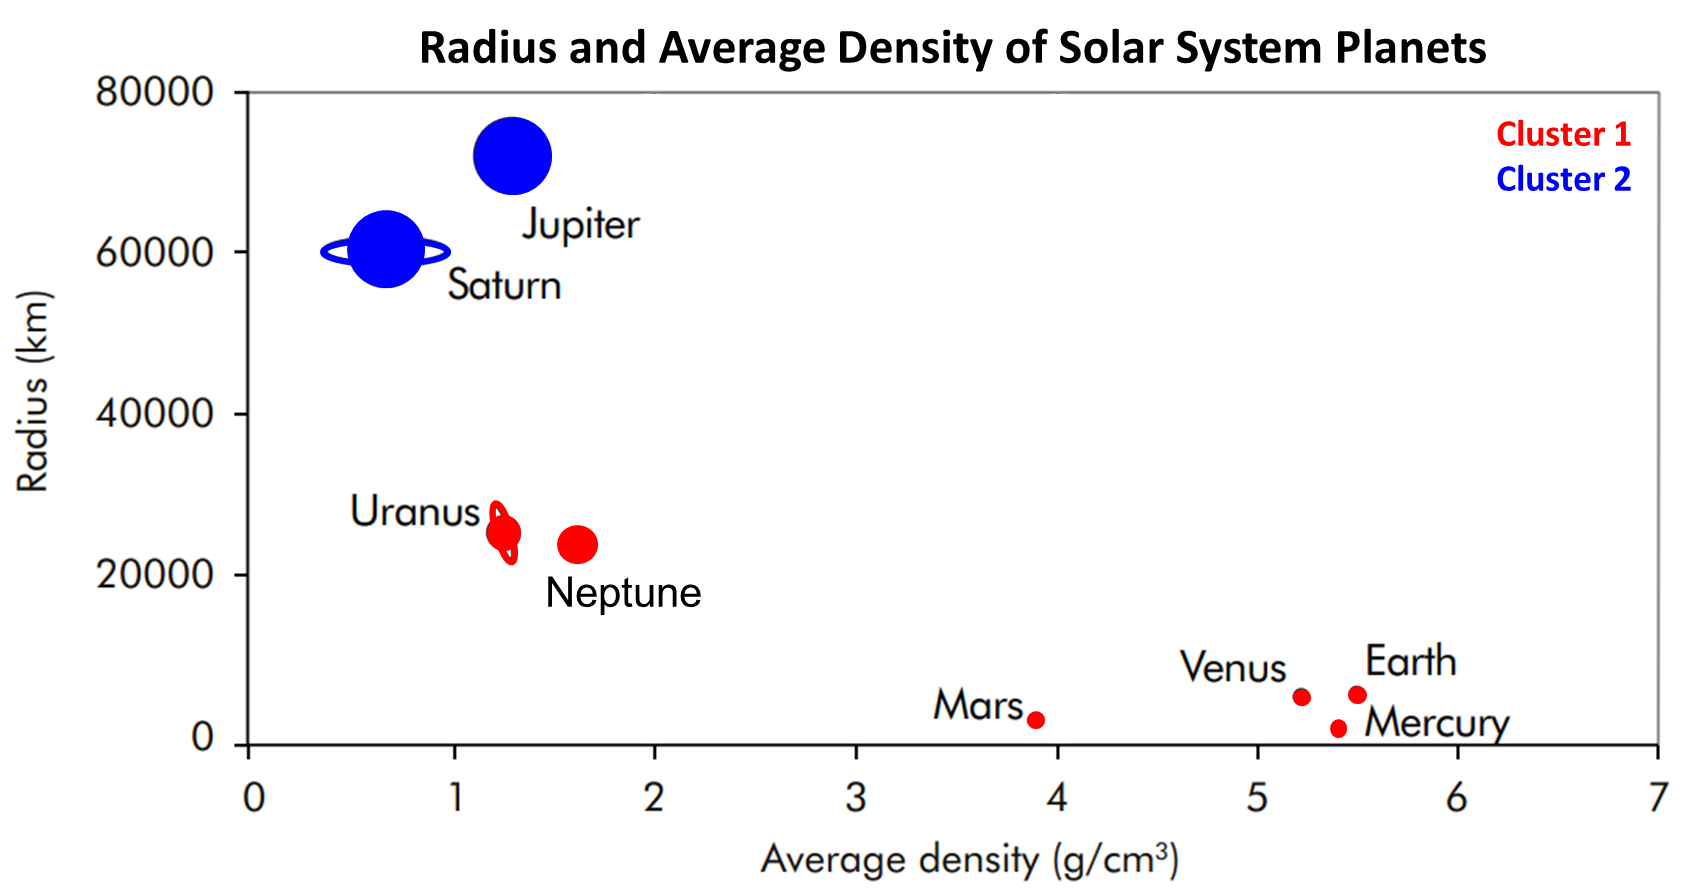

This is probably not how we expected the planets to cluster based on our reason to use k = 2. However, if we delve deeper into the information we were given before: 

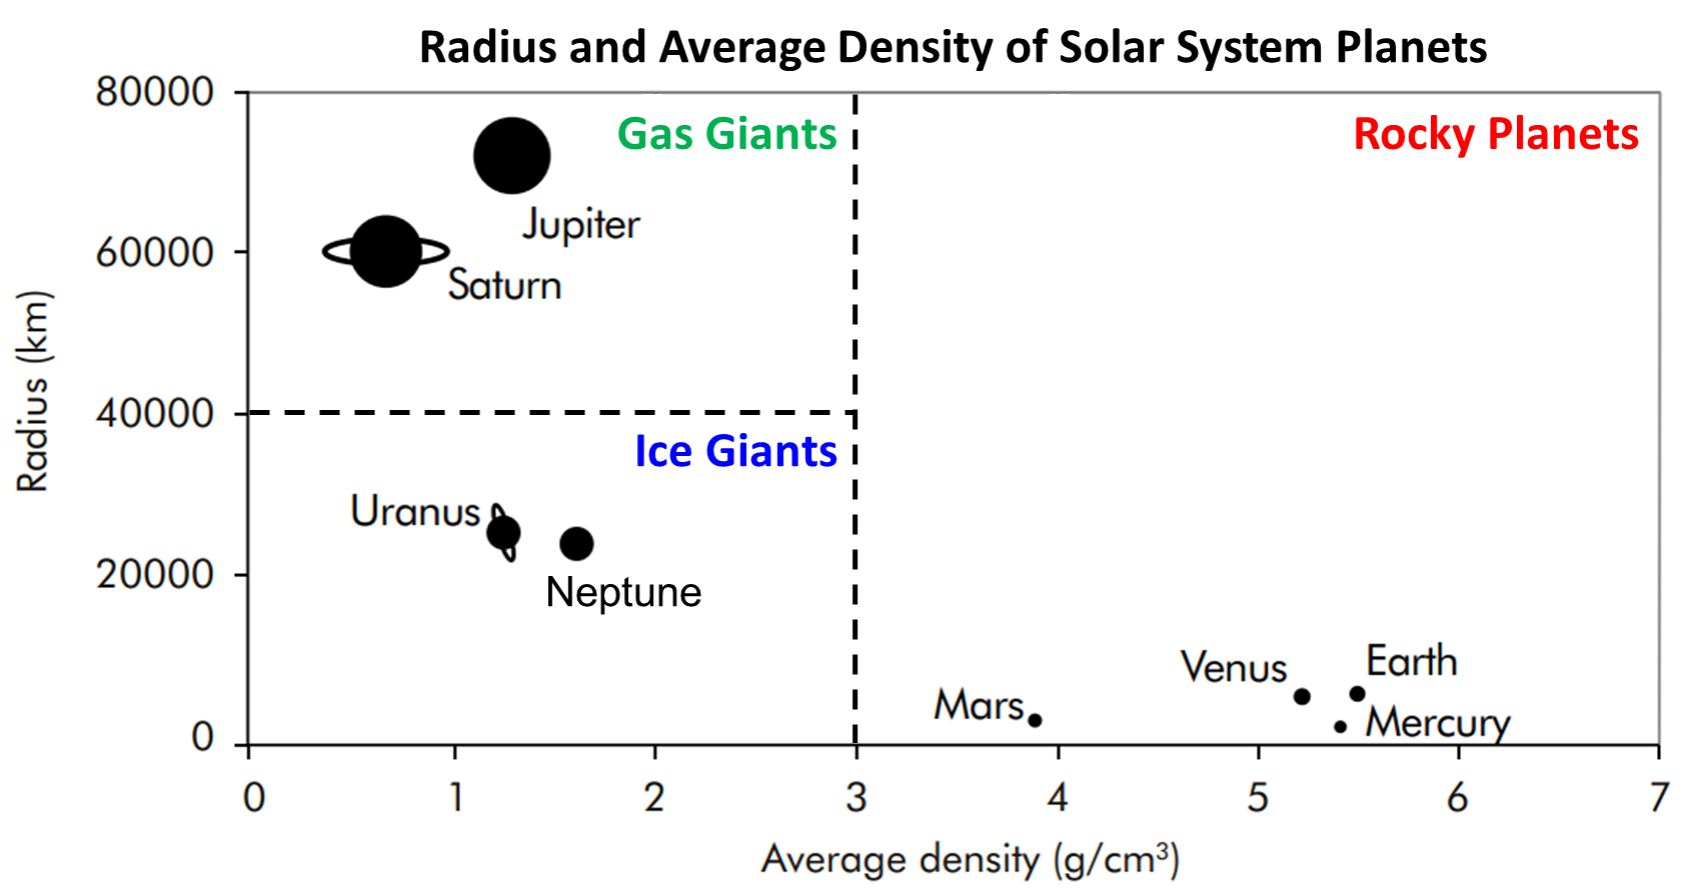

Let's see how the planets cluster based on k-means clustering with k = 3: 

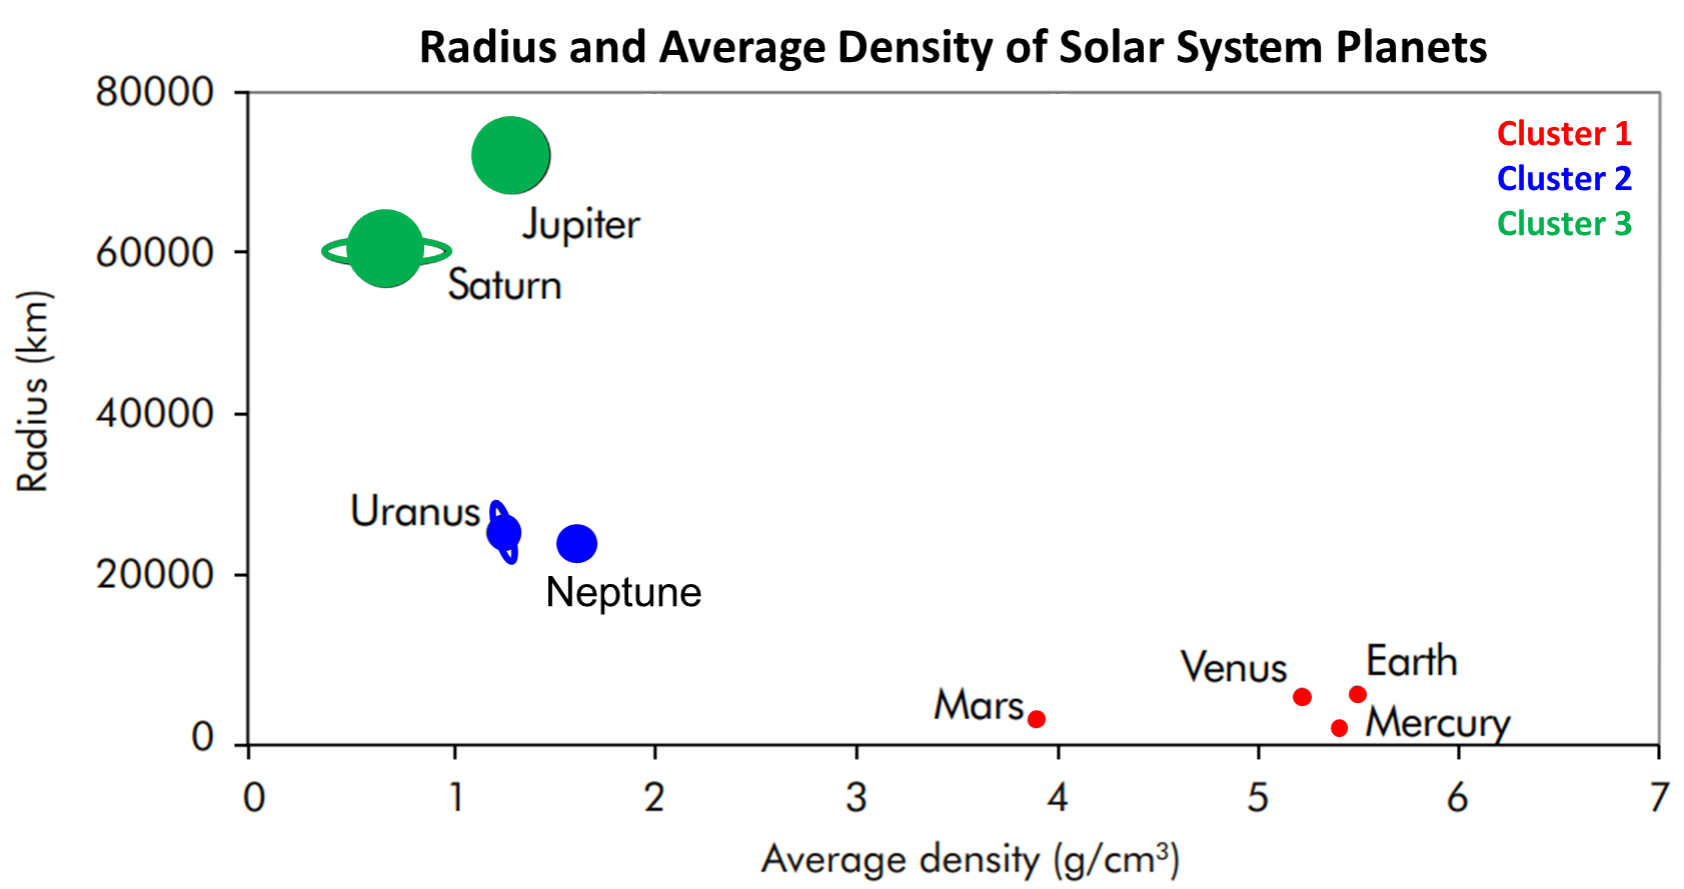

Now our results match what we expected based on our reason to use k = 3.

### Silhouette Analysis

You must be wondering: what if we don't have any prior knowledge of the data? What value do we use for k, and how do we know if this was a good choice? To consider these questions, we can conduct a **silhouette analysis** to determine which k value best minimizes the in-cluster sum of squares**. **For this analysis, we calculate the silhouette value for each observation and assess how they compare within a cluster by generating a **silhouette plot**. The silhouette value measures how similar an observation is to its own cluster compared to others based on a distance metric. This value ranges from -1 to 1, where a higher positive value implies that an observation is well-matched to its cluster and vice-versa. 

One way to assess whether we chose a good value for k is to evaluate the mean of all silhouette values. For the purposes of this lesson, we'll refer to this mean value as the **silhouette score**. In general, a silhouette score above 0.5 indicates that the data is well separated. We'll apply k-means clustering and silhouette analysis using the planetary data shown above: 

% Load and view planetary data


% Do k-means clustering and calculate silhouette score
% 1. Define data of interest

% 2. Apply kmeans function (use k = 3)

% 3. Determine silhouette values

% 4. Calculate the silhouette score


% Visualize the results
% 1. Plot of clustered data (using gscatter)

% 2. Silhouette plot (using silhouette)


Note: As the placement of cluster centroid is random for every iteration, clustering results may fluctuate between runs. The `kmeans` function contains additional properties that can be used to address this problem. For the purposes of this lesson, we'll use the `kmeans` function as is, but we'll keep in mind that our clustering results may differ between runs.

### Hierarchical vs. K-means Clustering

Both hierarchical clustering and k-means clustering are unsupervised learning methods for grouping data based on similarity. The difference between these two clustering methods is that hierarchical clustering takes a "bottom-up" approach, whereas k-means clustering takes a "top-down" approach.

In MATLAB, we can perform hierarchical clustering using the `clustergram` function, and k-means clustering using the `kmeans` function. The `silhouette` function is used to calculate the silhouette value for each observation based on its cluster assignment from k-means clustering. This function also generates a silhouette plot. 

# In-class practice: clustering of the Framingham data

## Applying hierarchical clustering based on health measurements

Let's say we want to know if individuals who suffered from a heart attack were similar across their health measurements (e.g. heartrate, BMI) using hierarchical clustering. We would also like to know if the health profile for this group was different from that of individuals who did not have a record of heart attack. The first step is to load the data and define the subset we're interested in:

% Load the Framingham data

% Load the health variables

% Subset the data to contain variables of interest


We'll remove rows containing NaN values and get the subset for the first 50 entries. We'll also create a variable for the heart attack occurrence and a numerical array for the health measurement data:

% Remove rows containing NaN values

% Retrieve subset of first 50 entries

% Define variable for heart attack occurrence

% Create a numerical array for health variables (sans heart attack)


Now we can perform hierarchical clustering for this data subset. For this example, we'll use Euclidean distance (default) as our distance metric for assessing similarity. We'll also cluster along both rows and columns (default) and provide labels (rows = heart attack occurrence, columns = health measurements). Finally, we'll standardize each column to better compare measurements between patients:

% Define array of variable names

% Apply hierarchical clustering using the clustergram function


This clustergram shows how specific measurements compare between patient clusters, and which patients are most similar based on Euclidean distance. 

Question: Did individuals who suffered from a heart attack cluster together?

Let's see how the clustergram changes if we use Pearson's correlation to calculate the distance between patients:

% Apply hierarchical clustering, using correlation as the distance metric


Question: How did the clustering change when using correlation as our distance metric? Did individuals who suffered from a heart attack cluster together?

## Applying k-means clustering for the Framingham data

To more easily visualize k-means clustering, we'll consider how the previous set of patients cluster solely based on cholesterol and LDLC levels: 

% Define the data to use


Let's see if we're able to pick out diabetic patients from our data using k = 2: 

% Define data to use for kmeans

% Apply k-means clustering using k = 2

% Determine the silhouette values

% Calculate the silhouette score


Let's visualize a scatter plot of our data clustered into 2 groups. We'll also visualize the same plot, but now labelled according to heart attack occurrence:

% Visualize the results
% 1. Plot of clustered data (using gscatter)

% 2. Plot of data labelled by heart attack occurrence (using gscatter)


Question: Does one of our clusters encompass individuals who have suffered from heart attack?

Activity: How can we modify the code above to apply k-means clustering for k = 3? How does the s_score value compare between k = 3 and k = 2?

# Dimensionality Reduction - Representing the variability in the dataset in lower dimensions

Biomedical data is often tremendously large and highly complex. Thus, it's hard to interpret this data when considering all the information available. By applying **dimensionality reduction**, we can transform the data into a lower-dimension representation that is much easier to interpret. In this lesson, we'll go over one type of dimensionality reduction method known as **principal component analysis**, or **PCA**. 

## Principal Component Analysis

In PCA, an orthogonal linear transformation is applied to the data, projecting it onto a new coordinate system defined by principal components. 

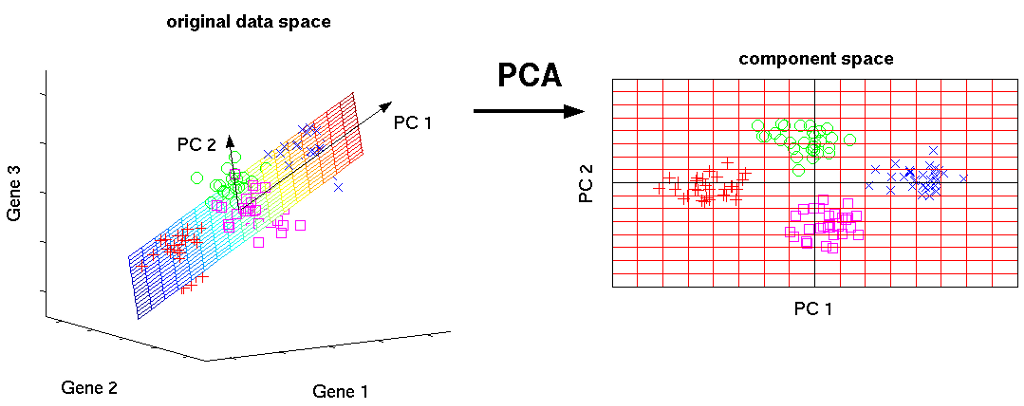

A **principal component (PC)** is a vector of weight (or coefficient) values assigned to each **feature**, or descriptive variable. Note that the number of features dictates the number of PCs that are determined. In the image below, **P** represents the matrix of PC coefficients that are used to linearly transform the original data (**X**) into a new representative data (**Y**) that can be visualized in in PC space:

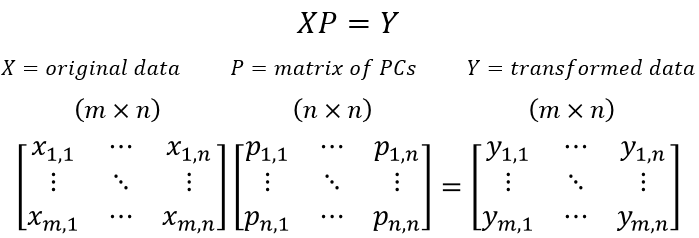

In PCA, P (matrix of PC coefficients) is typically determined by (1) **eigenvalue decomposition (EVD)** of the data covariance matrix, or (2) **singular vector decomposition (SVD)** of the data. For this lesson, we'll not delve into the specifics of how EVD or SVD is applied (for more information, refer to [this link](https://builtin.com/data-science/step-step-explanation-principal-component-analysis) for EVD and [this link](https://towardsdatascience.com/svd-8c2f72e264f) for SVD). 

Note: refer to the `pca` MATLAB documention for additional information on algorithms used for PCA. 

### Why do PCA?

The main goal when conducting PCA is to determine a reduced representation of the original data that can be visualized. This is done by determining a ranked list of linearly independent principal components that altogether describe the variance within the data. This list of PCs is ranked by decreasing percentage of variance explained, where the first PC explains the most variance, or is best representative, of the data. The figure below shows an example of how much variance each PC explains for a dataset with 10 features: 

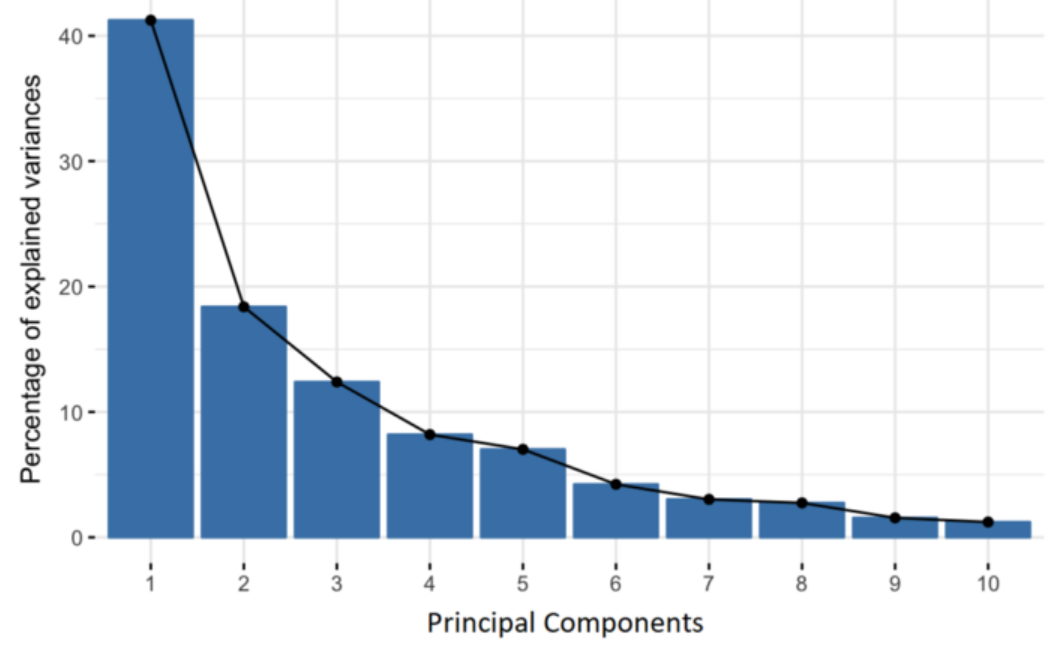

For the example shown above, we are able to represent ~60% of the variance using the first two PCs. In other words, if we were to plot the data based on PC1 and PC2, we would be visualizing a two-dimensional representation of the data that explains ~60% of the variance. 

Note 1: PCs differ in the **weights** (or coefficients) associated with the features. If a PC (e.g. PC1) can describe most of the variance in the data (> 50%), then we can evaluate the coefficients in this PC to see which feature(s) are most important (have the greatest absolute weight). In other words, the coefficient values for a PC can tell us which features are most responsible for the patterns seen in our data.

Note 2: As the new representations of the observations in the PC space are linear combinations of the original variables (features), it's important to **standardize the data** before conducting PCA. This ensures a unit variance for all variables, thus allowing comparable contributions from all variables when the data is transformed. In other words, normalizing the data reduces any bias there might be for a particular feature.

In MATLAB, the `pca` function is used to perform PCA based on SVD. The `zscore` function can be used to standardize the data before doing PCA. 

### Example: applying PCA for the Framingham data

For this analysis, we'll consider the same dataset of health measurements we used for hierarchical clustering. Recall that this dataset contains 8 measurements, or features. This means that we'll be determining 8 linearly independent PCs by peforming PCA. Let's first normalize this data (*X*) then determine the matrix of PC coefficients (*P*), the matrix of the transformed data (*Y*), and a vector for the variance explained by each PC (*explained*):

% Normalize health data

% Do PCA (P = PC matrix, Y = transformed data, explained = variance explained)


Question: How much variance is exlained by PC1 and PC2?

Now we'll visualize our transformed data in the component space by plotting PC1 vs. PC2. We'll also use our variable for heart attack occurrence to label our data: 

% Visualize transformed data on PC1 vs. PC2 plot (label using heart attack occurrence)


Based on this plot, we can see that individuals who suffered from a heart attack cluster within the negative range along PC1. We can check the PC matrix (*P*) to see which features contribute the most for PC1: 

% Assess coefficient values for PC1


Question: Which features contribute the most to how the data is visualized along PC1? 

# Unsupervised vs. Supervised Learning

All of the methods discussed in this lesson serve as applications for unsupervised learning. In machine learning, we can also process data using **supervised learning**, where information on the output data (e.g. labels) is considered during the learning process. While unsupervised learing is used for data exploration, supervised learning is typically used to train and develop predictive or classification tools based on labeled data. 

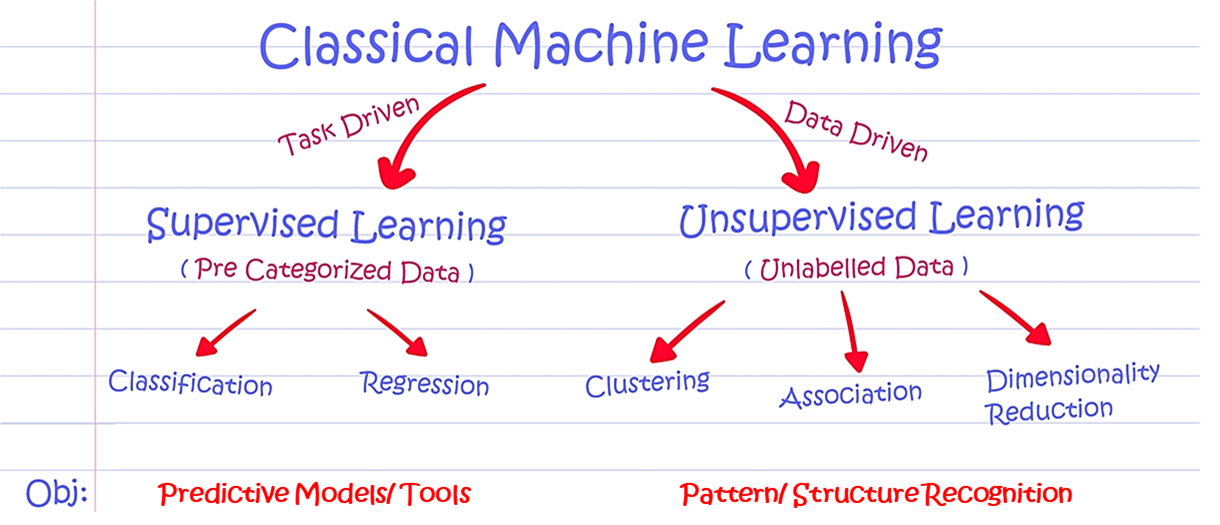

# Summary

- Unsupervised learning allows us to infer information about a dataset without any user guidance based on underlying similarities and patterns

- Common applications of unsupervised learning to analyze biomedical data include clustering (hierarchical, k-means) and dimensionality reduction (principal component analysis)

- Hierarchical clustering involves a "bottom-up" approach, whereas k-means clustering applies a "top-down" approach, to assign data into groups

- Principal component analysis (PCA) allows us to transform highly complex data into lower-dimension representations that are easier to interpret

- In contrast to unsupervised learning, supervised learning includes information on the output variables (e.g. labels) that can be used to train and develop predictive or classification tools 

### Built-in MATLAB functions covered in this lesson:

- `pdist`*:*                quantifies similarity using a distance metric (e.g. Euclidean, correlation)

- `clustergram`*:*    performs hierarchical clustering

- `kmeans`*:*              performs k-means clustering

- `silhouette`*:*      calculates silhouette values and generates a silhouette plot for k-means clustering 

- `pca`*:*                    performs principal component analysis (PCA)

- `zscore`*:*              normalizes each column in a matrix to have mean 0 and standard deviation of 1

### References for additional information:

- [Eigenvalue Decomposition (EVD)](https://builtin.com/data-science/step-step-explanation-principal-component-analysis)

- [Singular Vector Decomposition (SVD)](https://towardsdatascience.com/svd-8c2f72e264f)